# Teoria delle strutture - PROBLEMA 4

% serbatoio pieno d'acqua schematizzato come guscio sottile
%% Clear workspace and close any open windows
clear all
close all

## SOLUZIONE PUNTO 3 

% 3) Assumendo che il serbatoio possa essere schematizzato come un guscio sottile, scrivere
%l’equazione differenziale e le condizioni al bordo che permettono di determinare la soluzione
%di questo problema di equilibrio.

## SIMBOLICO (per risolvere il guscio)

syms z  A1 A2 E R nu t h gamma beta D real

p=-gamma*(h-z) % Carico idrostatico

$$p = -\gamma \,\left(h-z\right)$$

## Soluzione omogenea 

wo=A1*exp(-(beta*z)/(R*sqrt(2)))*cos((beta*z)/(R*sqrt(2)))... 
    +A2*exp(-(beta*z)/(R*sqrt(2)))*sin((beta*z)/(R*sqrt(2)))

$$wo = A_{1}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)+A_{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)$$

## Soluzione particolare

wp=(p*R^2)/(E*t)

$$wp = -\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}$$

## Soluzione

w(z)=wo+wp

$$w(z) = A_{1}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)+A_{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)-\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}$$

% Derivate
w_z(z)=diff(w,z) % derivata prima

$$w\_z(z) = \begin{array}{l} \frac{R^{2}\,\gamma }{\text{E}\,t}-\frac{\sqrt{2}\,A_{1}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{2\,R}+\frac{\sqrt{2}\,A_{2}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{2\,R}-\frac{\sqrt{2}\,A_{1}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)}{2\,R}-\frac{\sqrt{2}\,A_{2}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)}{2\,R}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

w_zz(z)=diff(w_z,z) % derivata seconda

$$w\_zz(z) = \frac{A_{1}\,\beta^{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)}{R^{2}}-\frac{A_{2}\,\beta^{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)}{R^{2}}$$

## CDS

% lo ricavo per imporre una condizione al contorno
 mz(z)=simplify(-D*w_zz)

$$mz(z) = \frac{\text{D}\,\beta^{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\left(A_{2}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)-A_{1}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)\right)}{R^{2}}$$

## SIMBOLICO ( per risolvere la piastra)

syms c1 c2 c3 r  real

## Soluzione piastra circolare

p2=-gamma*h %carico idrostatico sulla piastra

$$p2 = -\gamma \,h$$

w2(r)=p2*r^4/(64*D)+c1*r^2/4+c3

$$w2(r) = c_{3}+\frac{c_{1}\,r^{2}}{4}-\frac{\gamma \,h\,r^{4}}{64\,\text{D}}$$

## derivate di w2(r)

w2_r(r)=diff(w2,r) % derivata prima

$$w2\_r(r) = \frac{c_{1}\,r}{2}-\frac{\gamma \,h\,r^{3}}{16\,\text{D}}$$

w2_rr(r)=diff(w2_r,r) % derivata seconda

$$w2\_rr(r) = \frac{c_{1}}{2}-\frac{3\,\gamma \,h\,r^{2}}{16\,\text{D}}$$

## Ricavo mr

% lo ricavo per imporre una condizione al contorno
mr(r)=D*(-w2_rr-nu*w2_r/r)

$$mr(r) = -\text{D}\,\left(\frac{c_{1}}{2}+\frac{\nu \,\left(\frac{c_{1}\,r}{2}-\frac{\gamma \,h\,r^{3}}{16\,\text{D}}\right)}{r}-\frac{3\,\gamma \,h\,r^{2}}{16\,\text{D}}\right)$$

## Applico le Condizioni al contorno:

cc1=w(0)==0           % spostamento del guscio nullo                 

$$cc1 = A_{1}-\frac{R^{2}\,\gamma \,h}{\text{E}\,t}=0$$

cc2=w_z(0)==w2_r(-R)  % rotazioni uguali           

$$cc2 = \frac{\sqrt{2}\,A_{2}\,\beta }{2\,R}-\frac{\sqrt{2}\,A_{1}\,\beta }{2\,R}+\frac{R^{2}\,\gamma }{\text{E}\,t}=\frac{R^{3}\,\gamma \,h}{16\,\text{D}}-\frac{R\,c_{1}}{2}$$

cc3=w2(-R)==0         % spostamento piastra nullo                     

$$cc3 = c_{3}+\frac{R^{2}\,c_{1}}{4}-\frac{R^{4}\,\gamma \,h}{64\,\text{D}}=0$$

cc4=mr(-R)==mz(0)     % momenti uguali

$$cc4 = -\text{D}\,\left(\frac{c_{1}}{2}+\frac{\nu \,\left(\frac{R\,c_{1}}{2}-\frac{R^{3}\,\gamma \,h}{16\,\text{D}}\right)}{R}-\frac{3\,R^{2}\,\gamma \,h}{16\,\text{D}}\right)=\frac{A_{2}\,\text{D}\,\beta^{2}}{R^{2}}$$

## risolvo il sistema per trovare A1 , A2 , c1, c3

S=solve([cc1 cc2 cc3 cc4],[A1 A2 c1 c3]);    
A_1=simplify(S.A1(1))

$$A\_1 = \frac{R^{2}\,\gamma \,h}{\text{E}\,t}$$

A_2=simplify(S.A2(1))

$$A\_2 = -\frac{\sqrt{2}\,R^{2}\,\gamma \,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t-4\,\sqrt{2}\,\text{D}\,\beta \,h-4\,\sqrt{2}\,\text{D}\,\beta \,h\,\nu \right)}{8\,\text{D}\,\text{E}\,\beta \,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}$$

c_1=simplify(S.c1(1))

$$c\_1 = \frac{\gamma \,\left(3\,\text{E}\,R^{2}\,h\,t-16\,\text{D}\,\beta^{2}\,h+16\,\sqrt{2}\,\text{D}\,R\,\beta +\text{E}\,R^{2}\,h\,\nu \,t-\sqrt{2}\,\text{E}\,R^{2}\,\beta \,h\,t\right)}{8\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}$$

c_3=simplify(S.c3(1))

$$c\_3 = -\frac{R^{2}\,\gamma \,\left(5\,\text{E}\,R^{2}\,h\,t-32\,\text{D}\,\beta^{2}\,h+32\,\sqrt{2}\,\text{D}\,R\,\beta +\text{E}\,R^{2}\,h\,\nu \,t-\sqrt{2}\,\text{E}\,R^{2}\,\beta \,h\,t\right)}{64\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}$$

## spostamento piastra

w22(r)=simplify(subs(w2,[c1  c3],[c_1  c_3])) 

$$w22(r) = \frac{\gamma \,\left(R^{2}-r^{2}\right)\,\left(32\,\text{D}\,\beta^{2}\,h-5\,\text{E}\,R^{2}\,h\,t+\text{E}\,h\,r^{2}\,t-32\,\sqrt{2}\,\text{D}\,R\,\beta -\text{E}\,R^{2}\,h\,\nu \,t+\text{E}\,h\,\nu \,r^{2}\,t-\sqrt{2}\,\text{E}\,\beta \,h\,r^{2}\,t+\sqrt{2}\,\text{E}\,R^{2}\,\beta \,h\,t\right)}{64\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}$$

w22_r(r)=diff(w22,r) % derivata prima

$$w22\_r(r) = \begin{array}{l} \frac{\gamma \,\left(R^{2}-r^{2}\right)\,\left(2\,\text{E}\,h\,r\,t+2\,\text{E}\,h\,\nu \,r\,t-2\,\sqrt{2}\,\text{E}\,\beta \,h\,r\,t\right)}{64\,\text{D}\,\text{E}\,t\,\sigma_{1}}-\frac{\gamma \,r\,\left(32\,\text{D}\,\beta^{2}\,h-5\,\text{E}\,R^{2}\,h\,t+\text{E}\,h\,r^{2}\,t-32\,\sqrt{2}\,\text{D}\,R\,\beta -\text{E}\,R^{2}\,h\,\nu \,t+\text{E}\,h\,\nu \,r^{2}\,t-\sqrt{2}\,\text{E}\,\beta \,h\,r^{2}\,t+\sqrt{2}\,\text{E}\,R^{2}\,\beta \,h\,t\right)}{32\,\text{D}\,\text{E}\,t\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\nu -\sqrt{2}\,\beta +1 \end{array}$$

w22_rr(r)=diff(w22_r,r) % derivata seconda

$$w22\_rr(r) = \begin{array}{l} \frac{\gamma \,\left(R^{2}-r^{2}\right)\,\left(2\,\text{E}\,h\,t+2\,\text{E}\,h\,\nu \,t-2\,\sqrt{2}\,\text{E}\,\beta \,h\,t\right)}{64\,\text{D}\,\text{E}\,t\,\sigma_{1}}-\frac{\gamma \,r\,\left(2\,\text{E}\,h\,r\,t+2\,\text{E}\,h\,\nu \,r\,t-2\,\sqrt{2}\,\text{E}\,\beta \,h\,r\,t\right)}{16\,\text{D}\,\text{E}\,t\,\sigma_{1}}-\frac{\gamma \,\left(32\,\text{D}\,\beta^{2}\,h-5\,\text{E}\,R^{2}\,h\,t+\text{E}\,h\,r^{2}\,t-32\,\sqrt{2}\,\text{D}\,R\,\beta -\text{E}\,R^{2}\,h\,\nu \,t+\text{E}\,h\,\nu \,r^{2}\,t-\sqrt{2}\,\text{E}\,\beta \,h\,r^{2}\,t+\sqrt{2}\,\text{E}\,R^{2}\,\beta \,h\,t\right)}{32\,\text{D}\,\text{E}\,t\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\nu -\sqrt{2}\,\beta +1 \end{array}$$

## spostamento guscio

w11(z)=simplify(subs(w,[A1 A2],[A_1 A_2]))

$$w11(z) = \begin{array}{l} \frac{R^{2}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{\text{E}\,t}-\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}+\frac{R^{2}\,\gamma \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)\,\left(8\,\text{D}\,\beta \,h-\sqrt{2}\,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t\right)+8\,\text{D}\,\beta \,h\,\nu \right)}{8\,\text{D}\,\text{E}\,\beta \,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

w11_z(z)=diff(w11,z) % derivata prima

$$w11\_z(z) = \begin{array}{l} \frac{R^{2}\,\gamma }{\text{E}\,t}-\frac{\sqrt{2}\,R\,\beta \,\gamma \,h\,{\mathrm{e}}^{-\sigma_{2}}\,\cos\left(\sigma_{2}\right)}{2\,\text{E}\,t}-\frac{\sqrt{2}\,R\,\beta \,\gamma \,h\,{\mathrm{e}}^{-\sigma_{2}}\,\sin\left(\sigma_{2}\right)}{2\,\text{E}\,t}+\frac{\sqrt{2}\,R\,\gamma \,{\mathrm{e}}^{-\sigma_{2}}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{\sigma_{3}}-\frac{\sqrt{2}\,R\,\gamma \,{\mathrm{e}}^{-\sigma_{2}}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{\sigma_{3}}\\ \mathrm{where}\\ \sigma_{1}=8\,\text{D}\,\beta \,h-\sqrt{2}\,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t\right)+8\,\text{D}\,\beta \,h\,\nu \\ \sigma_{2}=\frac{\sqrt{2}\,\beta \,z}{2\,R}\\ \sigma_{3}=16\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right) \end{array}$$

w11_zz(r)=diff(w11_z,z) % derivata seconda

$$w11\_zz(r) = \begin{array}{l} \frac{\beta^{2}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)}{\text{E}\,t}-\frac{\beta \,\gamma \,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)\,\left(8\,\text{D}\,\beta \,h-\sqrt{2}\,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t\right)+8\,\text{D}\,\beta \,h\,\nu \right)}{8\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

u(z)=simplify(int(w11,z)*nu/R)

$$u(z) = \begin{array}{l} \frac{\nu \,\left(\frac{4\,R^{2}\,\beta \,\gamma \,z^{2}\,\sigma_{1}+\frac{8\,R^{3}\,\gamma \,{\mathrm{e}}^{-\sigma_{2}}\,\sin\left(\sigma_{2}\right)\,\left(-h\,\beta^{2}+R+R\,\nu \right)}{\beta }-8\,R^{2}\,\beta \,\gamma \,h\,z\,\sigma_{1}-\frac{8\,R^{3}\,\gamma \,{\mathrm{e}}^{-\sigma_{2}}\,\cos\left(\sigma_{2}\right)\,\left(\sqrt{2}\,R\,\beta -2\,R\,\nu -R\,\nu^{2}-3\,\beta^{2}\,h-R+\sqrt{2}\,\beta \,h+\sqrt{2}\,\beta^{3}\,h-3\,\beta^{2}\,h\,\nu +\sqrt{2}\,\beta \,h\,\nu^{2}+\sqrt{2}\,R\,\beta \,\nu +2\,\sqrt{2}\,\beta \,h\,\nu \right)}{\beta \,\sigma_{1}}}{8\,\text{E}\,\beta \,t\,\sigma_{1}}+\frac{\sqrt{2}\,R^{5}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{2}}\,\sin\left(\frac{\pi \,R+2\,\sqrt{2}\,\beta \,z}{4\,R}\right)}{8\,\text{D}\,\beta^{2}\,\sigma_{1}}\right)}{R}\\ \mathrm{where}\\ \sigma_{1}=\nu -\sqrt{2}\,\beta +1\\ \sigma_{2}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

## Variabili numeriche

R_n=1000; % raggio serbatoio [mm]
E_n=210000; % Young's modulus steel [N/mm^2] se.. 2.1E11[N/m^2] 
nu_n=0.3; % coefficiente di Poisson acciaio
t_n=R_n/50; %spessore serbatoio
h_n=5*R_n; %altezza serbatoio
gamma_n=0.000001; % peso specifico dell'acqua N/mm3
p_n=-gamma_n*(h_n-z); % Carico idrostatico
D_n=(E_n*t_n^3)/(12*(1-nu_n^2)); % rigidezza flessionale
beta_n=((E_n*t_n*R_n^2)/D_n)^(1/4);
p2_n=-gamma_n*h_n;

## Problema in numerico

A1n=double(subs(A_1,[R gamma h E t],[R_n gamma_n h_n E_n t_n]));
A2n=double(subs(A_2,[R gamma h E t D beta nu],[R_n gamma_n h_n E_n t_n D_n beta_n nu_n]));
c1n=double(subs(c_1,[R gamma h E t D beta nu],[R_n gamma_n h_n E_n t_n D_n beta_n nu_n]));
c3n=double(subs(c_3,[R gamma h E t D beta nu],[R_n gamma_n h_n E_n t_n D_n beta_n nu_n]));

wgn(z)=simplify(subs(w,[A1 A2 beta R gamma h E t],[A1n A2n beta_n R_n gamma_n h_n E_n t_n]));
wpn(r)=simplify(subs(w2,[c1 c3 h D gamma],[c1n c3n h_n D_n gamma_n]));
% DERIVATE
wgn_z(z)=diff(wgn,z); % derivata prima
wgn_zz(z)=diff(wgn_z,z); % derivata seconda
wpn_r(r)=diff(wpn,r); % derivata prima
wpn_rr(r)=diff(wpn_r,r); % derivata seconda

## Plot Soluzione

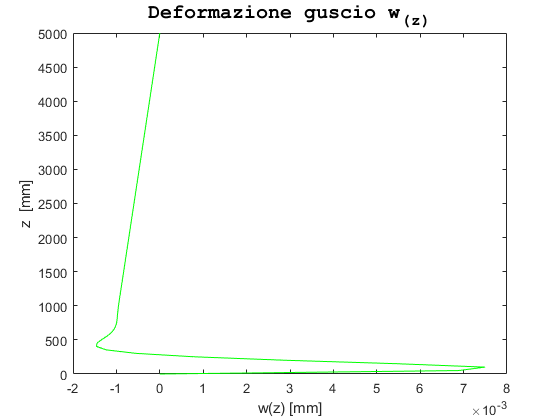

% Deformazione guscio
a=0:h_n/(100-1):h_n;
figure(1)
plot(double(wgn(a)),a,'g')
title(['\fontname{Courier}\fontsize{15}Deformazione guscio w_(_z_)'],'color','K');
ylabel('z  [mm]');
xlabel('w(z) [mm]');
hold on

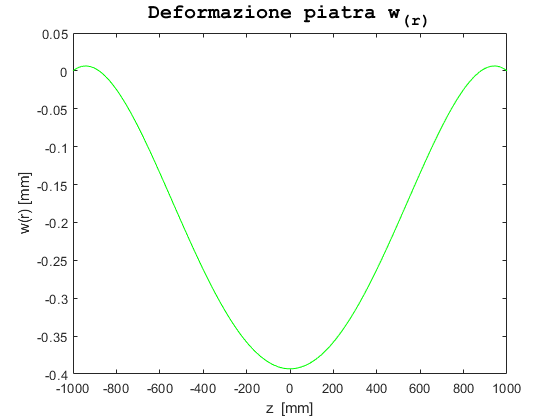

% Deformazione piastra
figure(2)
a2=-R_n:R_n/(100-1):R_n;
plot(a2,double(wpn(a2)),'g')
title(['\fontname{Courier}\fontsize{15}Deformazione piatra w_(_r_)'],'color','K');
xlabel('z  [mm]');
ylabel('w(r) [mm]');
hold on

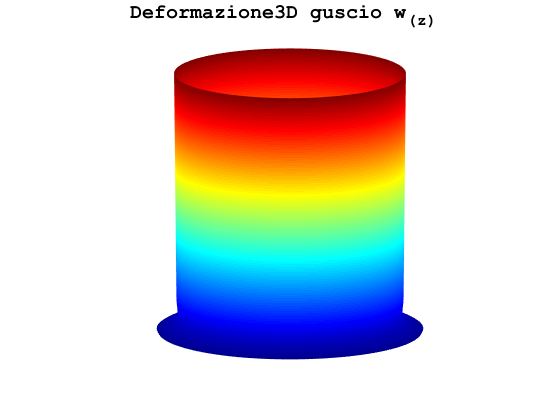


%Deformazione3D guscio
figure(3)
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
colormap(jet(100))
c=20000; % coefficiente che amplifica la deformazione
w1_n=R_n+(double(wgn(a))*c);
[X,Y,Z]=cylinder(w1_n,100);
s1=surface(X,Y,Z,'FaceAlpha',1,'EdgeColor','k','LineWidth',0.01);
title(['\fontname{Courier}\fontsize{15}Deformazione3D guscio w_(_z_) '],'color','K');
axis off
shading interp;
axis square
rotate3d;
view([39.700 12.400])

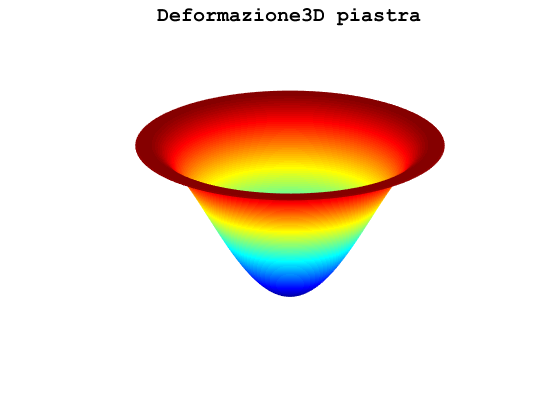

figure(10)
colormap(jet(100))
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
%Deformazione3D piastra
a3 = linspace(0, 2*pi, 100);      % Angle
rn = linspace(0, R_n, 100);       % Radius
c=30;
[A,R2]=meshgrid(a3, rn);       % Creat Mesh Matrices
fr=double(wpn(R2));           % Evaluate Function Of ‘R2’ Matrix
[xm,ym,zm]=pol2cart(A,R2,fr);  % Convert To Cartesian
surface(xm, ym, zm)
title(['\fontname{Courier}\fontsize{15}Deformazione3D piastra'],'color','K');
axis off
shading interp;
hold on
view(3)

## CDS piastra

tr(r)=simplify(-p2*r/2)

$$tr(r) = \frac{\gamma \,h\,r}{2}$$

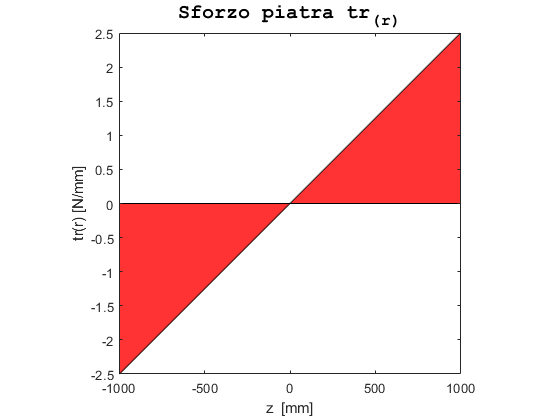

%% Plot the ns(z) stresses
a2=-R_n:R_n/(100-1):R_n;
figure(4)
area(a2,double((-p2_n*a2/2)),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo piatra tr_(_r_)'],'color','K');
xlabel('z  [mm]');
ylabel('tr(r) [N/mm]');
axis square


mr(r)=simplify(D*(-w2_rr(r)-nu*w2_r(r)/r))

$$mr(r) = \frac{3\,\gamma \,h\,r^{2}}{16}-\frac{\text{D}\,c_{1}}{2}-\frac{\text{D}\,c_{1}\,\nu }{2}+\frac{\gamma \,h\,\nu \,r^{2}}{16}$$

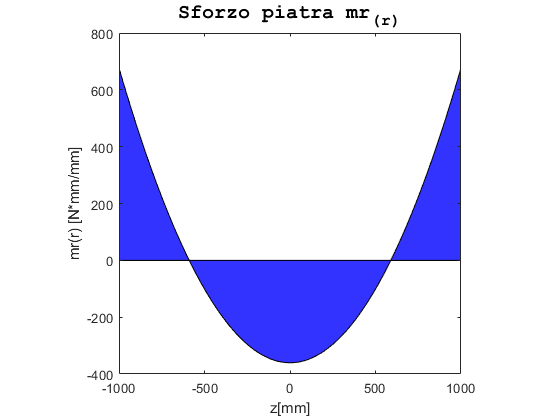

%% Plot the mr(r) stresses
figure(5)
mr_n(r)=simplify((D_n*(-wpn_rr-nu_n*wpn_r/r)));
area(a2,double(mr_n(a2)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo piatra mr_(_r_)'],'color','K');
xlabel('z[mm]');
ylabel('mr(r) [N*mm/mm]');
axis square


m_theta(r)=simplify(D*(-w2_r(r)/r-nu*w2_rr(r)))

$$m\_theta(r) = \frac{\gamma \,h\,r^{2}}{16}-\frac{\text{D}\,c_{1}}{2}-\frac{\text{D}\,c_{1}\,\nu }{2}+\frac{3\,\gamma \,h\,\nu \,r^{2}}{16}$$

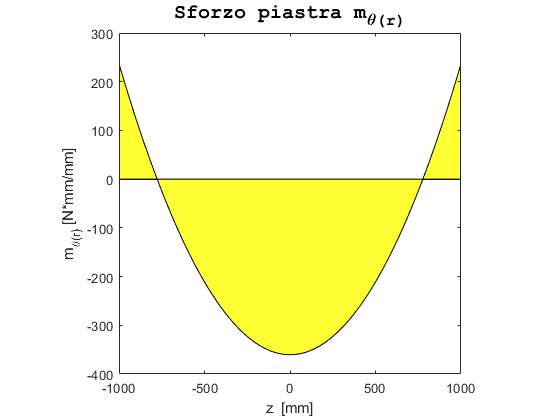

%% Plot the mtheta(r) stresses
figure(6)
mn_theta(r)=simplify(D_n*(-wpn_r(r)/r-nu_n*wpn_rr(r)));
area(a2,double(mn_theta(a2)),'FaceColor','y','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo piastra m_\theta_(_r_)'],'color','K');
xlabel('z  [mm]');
ylabel('m_\theta_(_r_) [N*mm/mm]');
axis square

##  CDS guscio

ns(z)=simplify(-w11*E*t/R)

$$ns(z) = \begin{array}{l} -\frac{\text{E}\,t\,\left(\frac{R^{2}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{\text{E}\,t}-\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}+\frac{R^{2}\,\gamma \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)\,\left(8\,\text{D}\,\beta \,h-\sqrt{2}\,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t\right)+8\,\text{D}\,\beta \,h\,\nu \right)}{8\,\text{D}\,\text{E}\,\beta \,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}\right)}{R}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

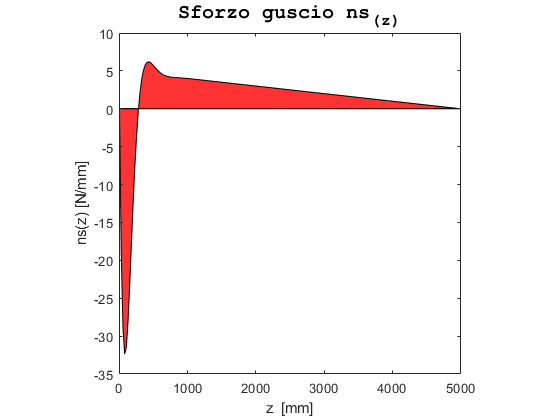

%% Plot the ns(z) stresses
a=0:h_n/(200-1):h_n;
figure(7)
area(a,double(-wgn(a)*E_n*t_n/R_n),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio ns_(_z_)'],'color','K');
xlabel('z  [mm]');
ylabel('ns(z) [N/mm]');
axis square


mz(z)=simplify(-D*w11_zz)

$$mz(z) = \begin{array}{l} -\text{D}\,\left(\frac{\beta^{2}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)}{\text{E}\,t}-\frac{\beta \,\gamma \,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)\,\left(8\,\text{D}\,\beta \,h-\sqrt{2}\,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t\right)+8\,\text{D}\,\beta \,h\,\nu \right)}{8\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

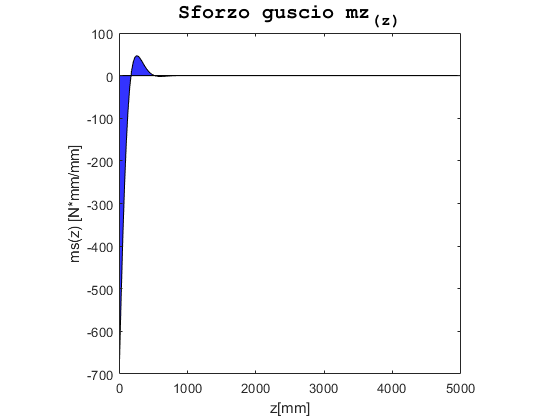

%% Plot the mz(z) stresses
figure(8)
mz_n(z)=(wgn_zz*D_n);
area(a,double(mz_n(a)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio mz_(_z_)'],'color','K');
xlabel('z[mm]');
ylabel('ms(z) [N*mm/mm]');
axis square


tz(z)=simplify(diff(mz))

$$tz(z) = \begin{array}{l} -\text{D}\,\left(\frac{\sqrt{2}\,\beta^{3}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{2}}\,\cos\left(\sigma_{2}\right)}{\sigma_{4}}-\frac{\sqrt{2}\,\beta^{3}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{2}}\,\sin\left(\sigma_{2}\right)}{\sigma_{4}}+\frac{\sqrt{2}\,\beta^{2}\,\gamma \,{\mathrm{e}}^{-\sigma_{2}}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{\sigma_{3}}+\frac{\sqrt{2}\,\beta^{2}\,\gamma \,{\mathrm{e}}^{-\sigma_{2}}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{\sigma_{3}}\right)\\ \mathrm{where}\\ \sigma_{1}=8\,\text{D}\,\beta \,h-\sqrt{2}\,\left(8\,\text{D}\,R+8\,\text{D}\,R\,\nu +\text{E}\,R^{2}\,h\,t\right)+8\,\text{D}\,\beta \,h\,\nu \\ \sigma_{2}=\frac{\sqrt{2}\,\beta \,z}{2\,R}\\ \sigma_{3}=16\,\text{D}\,\text{E}\,R\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)\\ \sigma_{4}=2\,\text{E}\,R\,t \end{array}$$

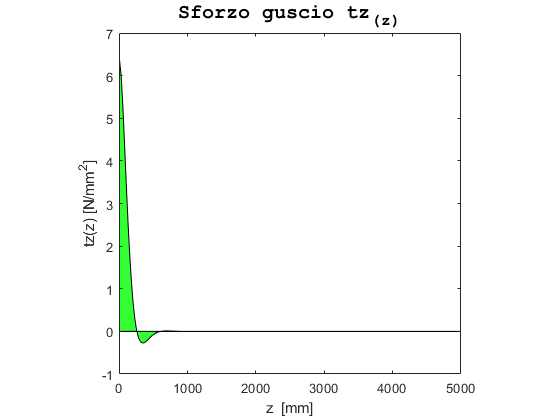

%% Plot the ns(z) stresses
figure(9)
tz_n(z)=diff(mz_n);
area(a,double(tz_n(a)),'FaceColor','g','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio tz_(_z_)'],'color','K');
xlabel('z  [mm]');
ylabel('tz(z) [N/mm^2]');
axis square

## SOLUZIONE PUNTO 4

% 4) Determinare le espressioni dello spostamento trasversale e delle caratteristiche della
%sollecitazione (semplificare il problema relativamente al calcolo delle componenti flessionali
%della sollecitazione, assumendo nel calcolo che il guscio sia di lunghezza infinita).

## Calcolo theta(-R) della piastra

theta(r)=simplify(w22_r(r))

$$theta(r) = -\frac{\gamma \,r\,\left(16\,\text{D}\,\beta^{2}\,h-3\,\text{E}\,R^{2}\,h\,t+\text{E}\,h\,r^{2}\,t-16\,\sqrt{2}\,\text{D}\,R\,\beta -\text{E}\,R^{2}\,h\,\nu \,t+\text{E}\,h\,\nu \,r^{2}\,t-\sqrt{2}\,\text{E}\,\beta \,h\,r^{2}\,t+\sqrt{2}\,\text{E}\,R^{2}\,\beta \,h\,t\right)}{16\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)}$$

k=simplify(mr(-R)/theta(-R)) % costante della molla

$$k = \frac{16\,\text{D}\,\text{E}\,t\,\left(\nu -\sqrt{2}\,\beta +1\right)\,\left(\frac{\text{D}\,c_{1}}{2}+\frac{\text{D}\,c_{1}\,\nu }{2}-\frac{3\,R^{2}\,\gamma \,h}{16}-\frac{R^{2}\,\gamma \,h\,\nu }{16}\right)}{R\,\gamma \,\left(2\,\text{E}\,h\,t\,R^{2}+16\,\sqrt{2}\,\text{D}\,R\,\beta -16\,\text{D}\,h\,\beta^{2}\right)}$$

## Valutazione numerica

Kn=double(mr_n(-R_n)/wpn_r(-R_n))

Kn =     2925748.79


%% reimposto il problema con le condizioni al contorno dovute alla molla

## Applico le Condizioni al contorno:

cc1=w(0)==0                        % spostamento del guscio nullo                 

$$cc1 = A_{1}-\frac{R^{2}\,\gamma \,h}{\text{E}\,t}=0$$

cc2=w_z(0)==double(mr_n(-R_n)/Kn)  % rotazioni                               

$$cc2 = \frac{\sqrt{2}\,A_{2}\,\beta }{2\,R}-\frac{\sqrt{2}\,A_{1}\,\beta }{2\,R}+\frac{R^{2}\,\gamma }{\text{E}\,t}=\frac{8459484659262361}{36893488147419103232}$$

S=solve([cc1 cc2],[A1 A2]);    
A_11=simplify(S.A1(1));
A_22=simplify(S.A2(1));
An_11=double(subs(A_11,[R gamma h E t],[R_n gamma_n h_n E_n t_n]));
An_22=double(subs(A_22,[R gamma h E t beta],[R_n gamma_n h_n E_n t_n beta_n]));
%Spostamento
wgn2(z)=simplify(subs(w,[A1 A2 beta R gamma h E t],[An_11 An_22 beta_n R_n gamma_n h_n E_n t_n]));
% Derivate
wgn2_z(z)=diff(wgn2,z); % derivata prima
wgn2_zz(z)=diff(wgn2_z,z); % derivata seconda
% CDS
ns2(z)=simplify(-wgn2*E_n*t_n/R_n);
mz2_n(z)=(-wgn2_zz*D_n);
tz2_n(z)=diff(mz2_n);

## Plot con K=0.15 

caso in cui le deformazioni e le CDS sono uguali a quelle ottenute nel punto 3

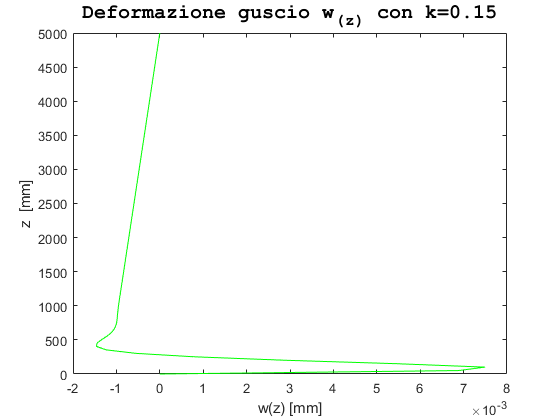

a=0:h_n/(100-1):h_n;
% DEFORMAZIONE
figure(11)
plot(double(wgn2(a)),a,'g')
title(['\fontname{Courier}\fontsize{15}Deformazione guscio w_(_z_) con k=0.15'],'color','K');
ylabel('z  [mm]');
xlabel('w(z) [mm]');
hold on

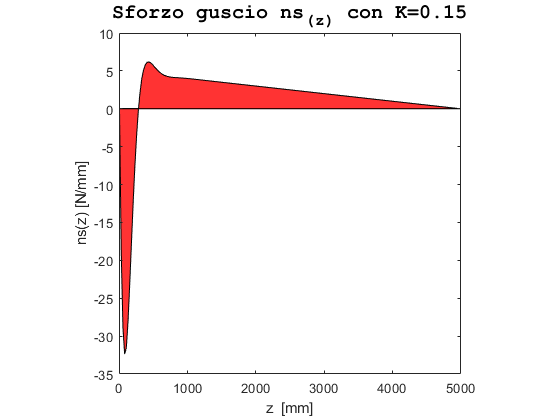

% CDS
%% Plot the ns(z) stresses
a=0:h_n/(200-1):h_n;
figure(7)
area(a,double(ns2(a)),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio ns_(_z_) con K=0.15'],'color','K');
xlabel('z  [mm]');
ylabel('ns(z) [N/mm]');
axis square

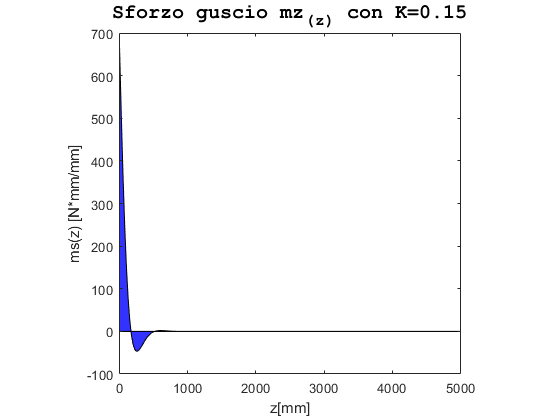

%% Plot the mz(z) stresses
figure(12)
area(a,double(mz2_n(a)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio mz_(_z_) con K=0.15'],'color','K');
xlabel('z[mm]');
ylabel('ms(z) [N*mm/mm]');
axis square

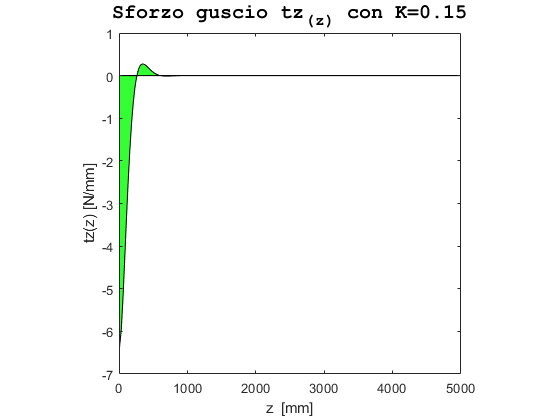

%% Plot the ns(z) stresses
figure(13)
area(a,double(tz2_n(a)),'FaceColor','g','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio tz_(_z_) con K=0.15'],'color','K');
xlabel('z  [mm]');
ylabel('tz(z) [N/mm]');
axis square

## Plot con K=inf

caso in cui le deformazioni e le CDS sono uguali a quelle ottenute nei punti 1 & 2

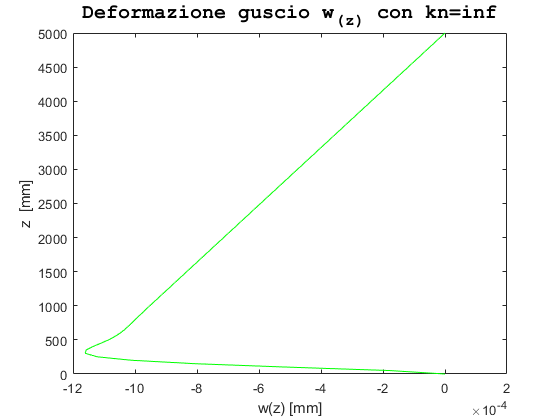

% Risolvo il sistema con Kn=0
Kn=inf;
cc1=w(0)==0;                       % spostamento del guscio nullo                 
cc2=w_z(0)==double(mr_n(-R_n)/Kn);  % rotazione                              
S=solve([cc1 cc2],[A1 A2]);    
A_11=simplify(S.A1(1));
A_22=simplify(S.A2(1));
An_11=double(subs(A_11,[R gamma h E t],[R_n gamma_n h_n E_n t_n]));
An_22=double(subs(A_22,[R gamma h E t beta],[R_n gamma_n h_n E_n t_n beta_n]));
%Spostamento
wgn2(z)=simplify(subs(w,[A1 A2 beta R gamma h E t],[An_11 An_22 beta_n R_n gamma_n h_n E_n t_n]));
% Derivate
wgn2_z(z)=diff(wgn2,z); % derivata prima
wgn2_zz(z)=diff(wgn2_z,z); % derivata seconda
% CDS
ns2(z)=simplify(-wgn2*E_n*t_n/R_n);
mz2_n(z)=(-wgn2_zz*D_n);
tz2_n(z)=diff(mz2_n);
%Plot
a=0:h_n/(100-1):h_n;
% DEFORMAZIONE
figure(14)
plot(double(wgn2(a)),a,'g')
title(['\fontname{Courier}\fontsize{15}Deformazione guscio w_(_z_) con kn=inf'],'color','K');
ylabel('z  [mm]');
xlabel('w(z) [mm]');
hold on

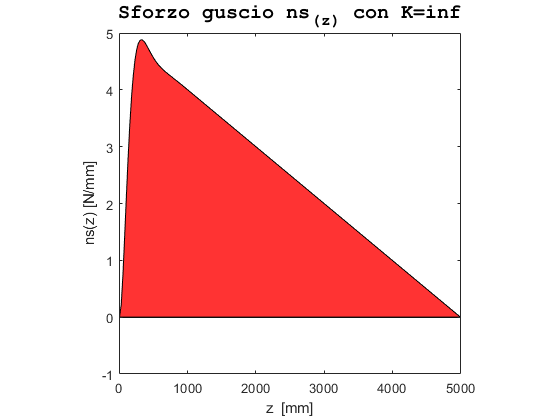

% CDS
%% Plot the ns(z) stresses
a=0:h_n/(200-1):h_n;
figure(7)
area(a,double(ns2(a)),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio ns_(_z_) con K=inf'],'color','K');
xlabel('z  [mm]');
ylabel('ns(z) [N/mm]');
axis square

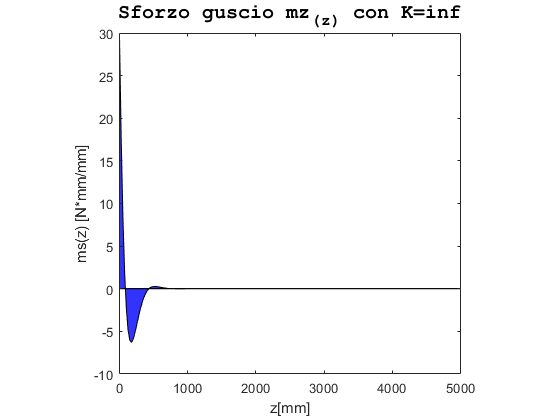

%% Plot the mz(z) stresses
figure(15)
area(a,double(mz2_n(a)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio mz_(_z_) con K=inf'],'color','K');
xlabel('z[mm]');
ylabel('ms(z) [N*mm/mm]');
axis square

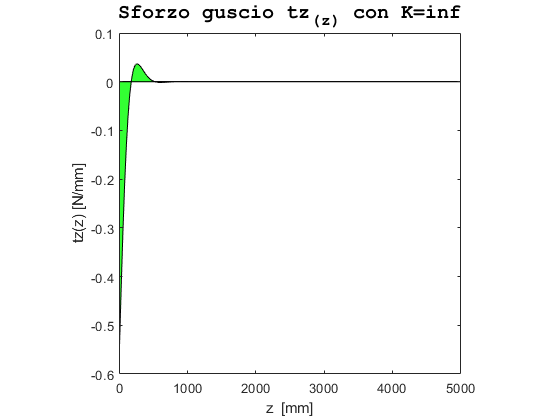

%% Plot the ns(z) stresses
figure(16)
area(a,double(tz2_n(a)),'FaceColor','g','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio tz_(_z_) con K=inf'],'color','K');
xlabel('z  [mm]');
ylabel('tz(z) [N/mm]');
axis square

## Plot con K=0 

caso in cui le deformazioni e le CDS sono uguali a quelle di un guscio semplicemente appoggiato, senza piastra circolare in fondo

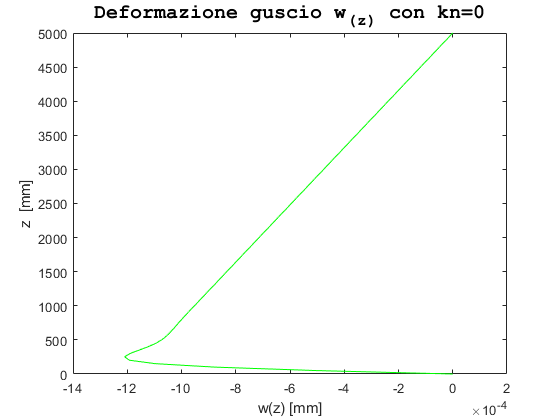

% Risolvo il sistema con Kn=0
Kn=0;
cc1=w(0)==0;                       % spostamento del guscio nullo                 
cc2=-w_zz(0)*D_n==double(Kn*wpn_r(-R_n));  % momento                              
S=solve([cc1 cc2],[A1 A2]);    
A_11=simplify(S.A1(1));
A_22=simplify(S.A2(1));
An_11=double(subs(A_11,[R gamma h E t],[R_n gamma_n h_n E_n t_n]));
An_22=double(subs(A_22,[R gamma h E t beta],[R_n gamma_n h_n E_n t_n beta_n]));
%Spostamento
wgn2(z)=simplify(subs(w,[A1 A2 beta R gamma h E t],[An_11 An_22 beta_n R_n gamma_n h_n E_n t_n]));
% Derivate
wgn2_z(z)=diff(wgn2,z); % derivata prima
wgn2_zz(z)=diff(wgn2_z,z); % derivata seconda
% CDS
ns2(z)=simplify(-wgn2*E_n*t_n/R_n);
mz2_n(z)=(-wgn2_zz*D_n);
tz2_n(z)=diff(mz2_n);
%Plot
a=0:h_n/(100-1):h_n;
% DEFORMAZIONE
figure(17)
plot(double(wgn2(a)),a,'g')
title(['\fontname{Courier}\fontsize{15}Deformazione guscio w_(_z_) con kn=0'],'color','K');
ylabel('z  [mm]');
xlabel('w(z) [mm]');
hold on

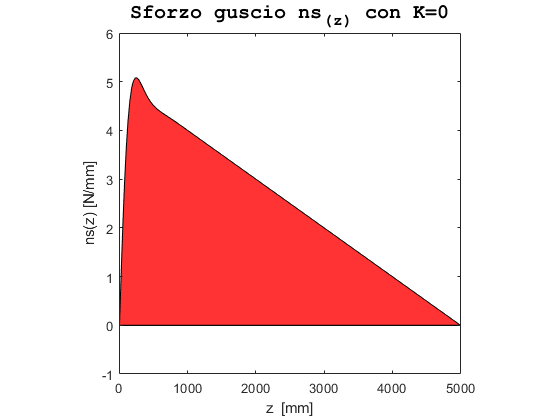

% CDS
%% Plot the ns(z) stresses
a=0:h_n/(200-1):h_n;
figure(7)
area(a,double(ns2(a)),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio ns_(_z_) con K=0'],'color','K');
xlabel('z  [mm]');
ylabel('ns(z) [N/mm]');
axis square

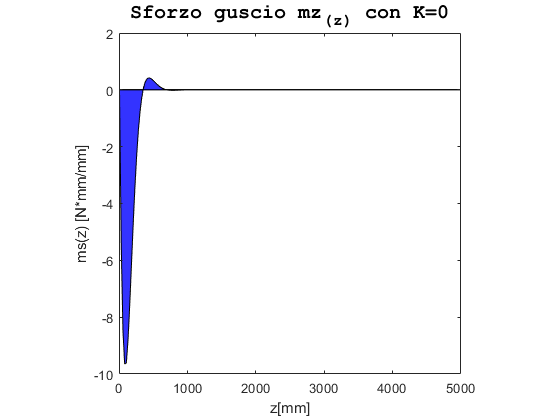

%% Plot the mz(z) stresses
figure(18)
area(a,double(mz2_n(a)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio mz_(_z_) con K=0'],'color','K');
xlabel('z[mm]');
ylabel('ms(z) [N*mm/mm]');
axis square

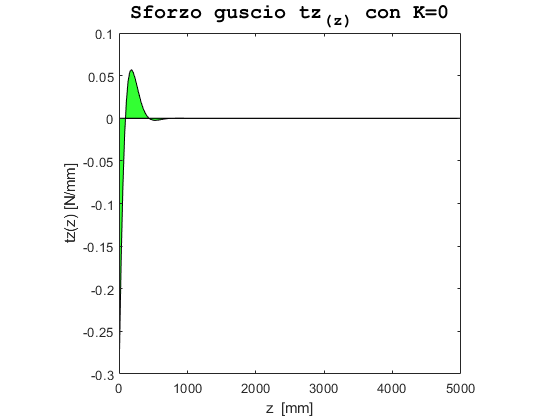

%% Plot the ns(z) stresses
figure(19)
area(a,double(tz2_n(a)),'FaceColor','g','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo guscio tz_(_z_) con K=0'],'color','K');
xlabel('z  [mm]');
ylabel('tz(z) [N/mm]');
axis square